# download image

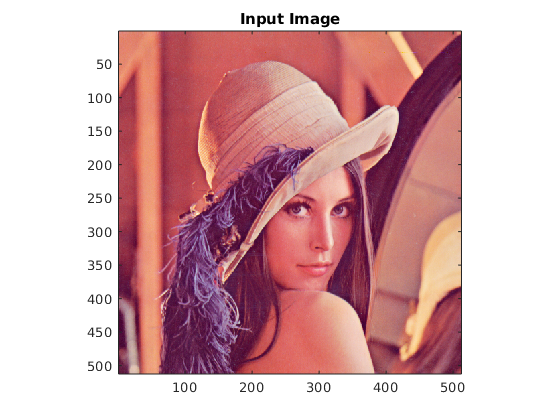

I = imread('https://upload.wikimedia.org/wikipedia/en/7/7d/Lenna_%28test_image%29.png');

%display image
figure(1); image(I); axis image
title('Input Image')

## crop the image by 50 pixels on each side

c = 50 

c = 50

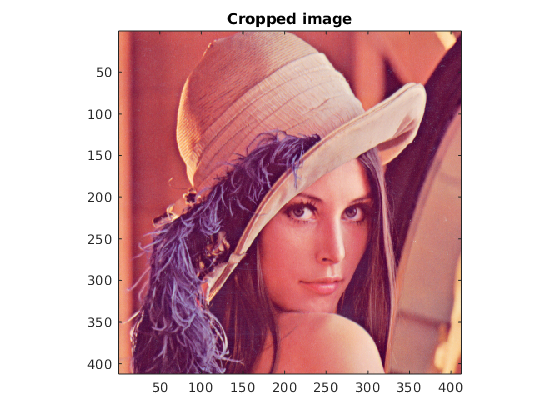


%fill your code here
Ic = I(c:end-c-1,c:end-c-1,:);

%display image
figure(2); image(Ic); axis image
title('Cropped image')

S = size(Ic)

S =    412   412     3


## convert image to grayscale

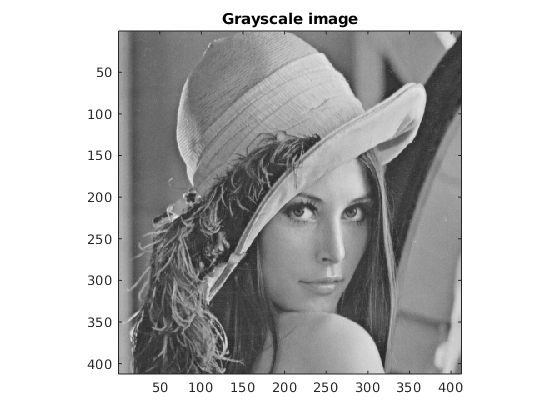

% GrayScale = 0.2989 * R + 0.5870 * G + 0.1140 * B 

% fill your code here
J = Ic;
for i = 1:S(1)
    for j = 1:S(2)
        for k = 1:S(3)
            J(i,j,k) = 0.2989 * Ic(i, j, 1) + 0.5870 * Ic(i, j, 2) + 0.1140 * Ic(i, j, 3);
        end
    end
end
J = uint8(J);

% Create 3-channel grayscale images (same value for all channels)

% fill your code here
K = Ic;
for i = 1:S(1)
    for j = 1:S(2)
        for k = 1:S(3)
            K(i,j,k) = 1/3 * Ic(i, j, 1) + 1/3 * Ic(i, j, 2) + 1/3 * Ic(i, j, 3);  
        end
    end
end
K = uint8(K);

figure(3); image(K); axis image;
title('Grayscale image')

## Highlight high/low intensity pixels

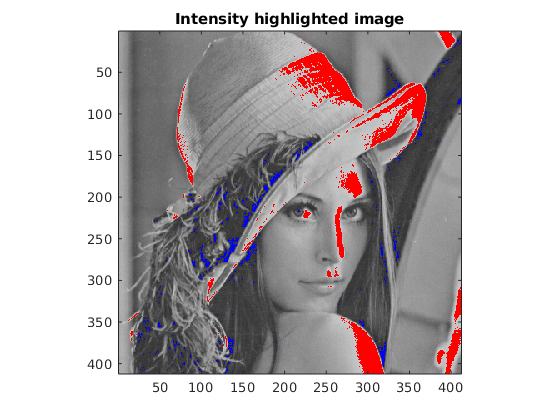

%- show high intensity pixels in red (I>200);
%- show low intensity in blue (I<50); 

L = K;

%fill your code here
for i = 1:S(1)
    for j = 1:S(2)
        if K(i,j,1) > 200
            L(i,j,:) = [255, 0, 0];
        elseif K(i,j,1) < 50
            L(i,j,:) = [0, 0, 255];
        end       
    end
end

figure(4); image(L); axis image
title('Intensity highlighted image')

## Add a yellow 10px-thick border around the resulting image

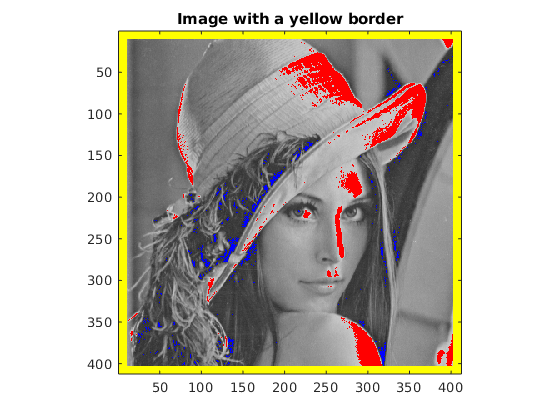

%fill your code here

M = L;

for i = 1:S(1)
    for j = 1:S(2)
        if (i < 11 || i > S(1)-10 || j < 11 || j > S(2)-10 )
            M(i,j,:) = [255, 255, 0];
        end
    end
end



figure(5); image(M); axis image
size(M);
title('Image with a yellow border');

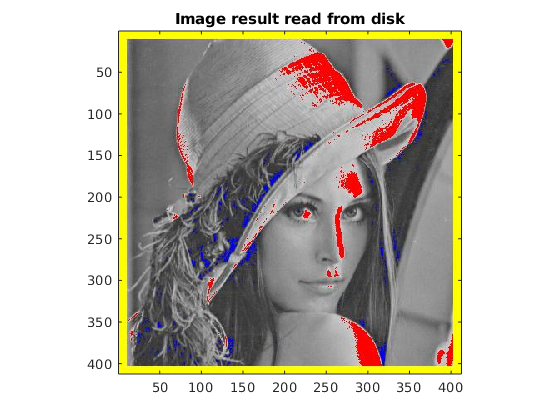


%store the image as JPEG
imwrite(M,'result.jpg')

%read from disk
N = imread('result.jpg');
figure(6); image(N); axis image
title('Image result read from disk')